% Definer parametere for R1, R2 og L
R1 = 10;  % Sett verdi for R1
R2 = 20;  % Sett verdi for R2
L = 0.5;  % Sett verdi for L i henry

% Definer telleren og nevneren for transferfunksjonen
numerator = [R2*L, 0];  % sL*R2
denominator = [R1*R2, (R1*L + R2*L), 0];  % R1*R2 + s(R1*L + R2*L)

% Opprett transferfunksjonen
G = tf(numerator, denominator);

% Vis transferfunksjonen
disp('Transferfunksjon for kretsen:');

Transferfunksjon for kretsen:


disp(G);

  tf with properties:

       Numerator: {[0 10 0]}
     Denominator: {[200 15 0]}
        Variable: 's'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]



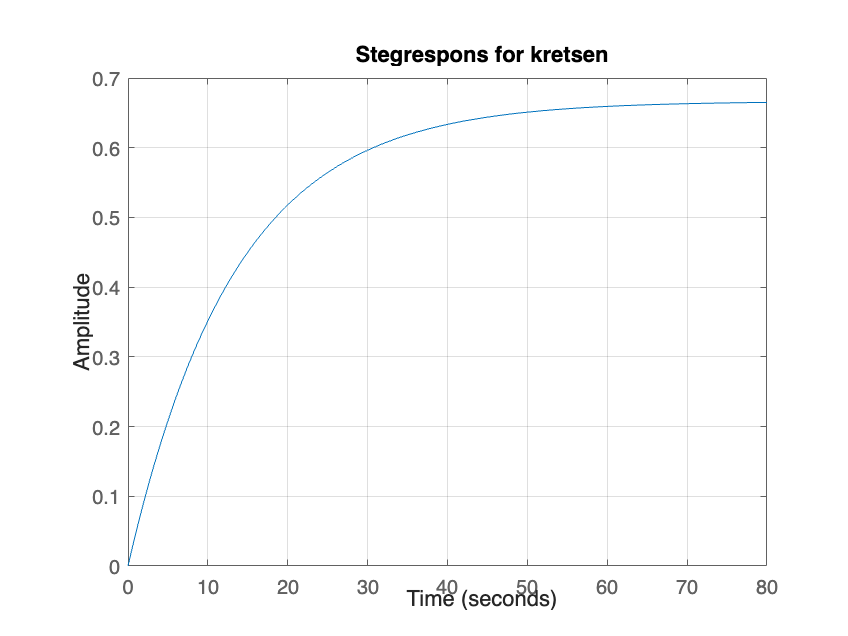


% Plott stegresponsen
figure;
step(G);
title('Stegrespons for kretsen');
grid on;